# Estimation of elastic properties of FB1_HTI sample

**Author**: Martin Rühlmann, Abakumov Ivan

**Publication date**: 25th October 2019

**E-mail**: abakumov_ivan@mail.ru

## Introduction

Some bla bla bla here))

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## 1. Upload the data

Sample = MLD('/remote/data/ivan/Ultrasonic_data/FB1-HTI/Sample_FB1_HTI_data.mat');

%  Data = load('/remote/data/ivan/Ultrasonic_data/FB1-HTI/Processed/FB1_HTI_PR.txt'); 
%  Sample.Theta  = Data(:,1);     % beta  [DEG] Grad
%  Sample.Theta(Sample.Theta>=360) = Sample.Theta(Sample.Theta>=360)-360;
%  Sample.Vp33 = Data(:,2);       % P-velocity in vertikaler (axial) "slow"
%  Sample.Vp11 = Data(:,3);       % P-velocity horizontal (radial) "fast"
%  Sample.Vs31 = Data(:,4);       % S-velocity vertical  (axial) "slow"
%  Sample.Vs21 = Data(:,5);       % S-velocity horizontal  (radial) "fast"
%  Sample.Vqp = Data(:,6);
%  Sample.rho = 2.52;


ind1 = 1:12;             % seria of measurements 
ind2 = 13:25;            % another at 90 degree

## Plot velocities

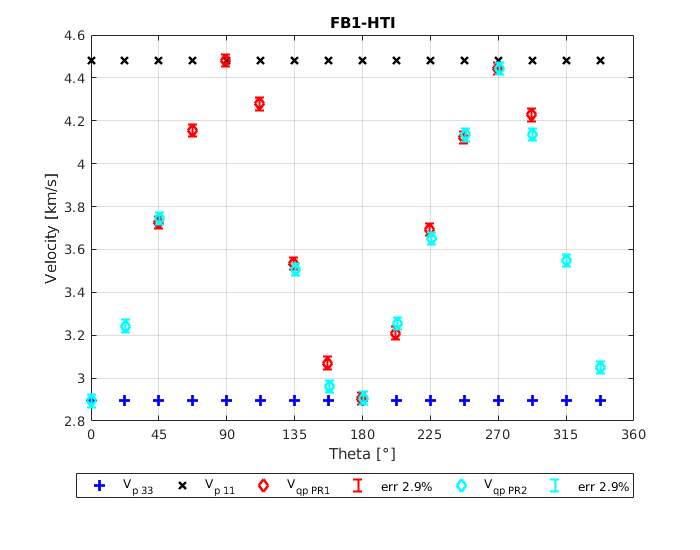

figure(1233)       % P velocities
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'Location', 'southoutside', 'Orientation','horizontal')
title('FB1-HTI')
xticks(0:45:360)
xticklabels(0:45:360)
axis([0 360 2.8 4.6]);
grid on

## 2. Conventional analyses of Thomsen's parameters

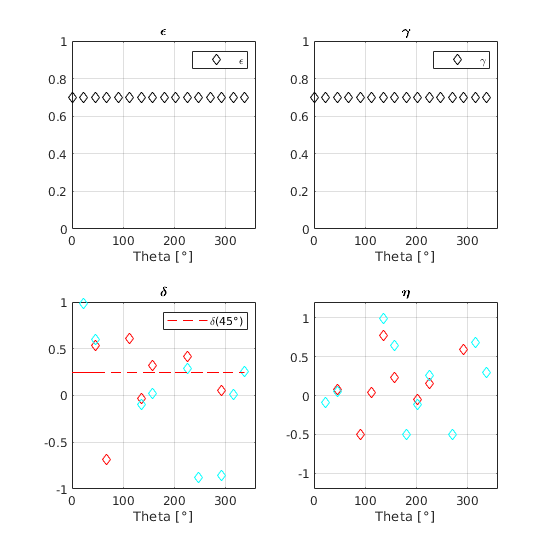

C11 = Sample.rho*Sample.Vp11.^2;
C33 = Sample.rho*Sample.Vp33.^2; 
C44 = Sample.rho*Sample.Vs31.^2; 
C66 = Sample.rho*Sample.Vs21.^2; 
Cqp = Sample.rho*Sample.Vqp.^2;
C12 = C11 - 2*C66;

ST2 = (sin(Sample.Theta/180*pi)).^2; 
CT2 = (cos(Sample.Theta/180*pi)).^2; 

A = (C11 + C44).*ST2 + (C33 + C44).*CT2; 
B = (C11 - C44).*ST2 - (C33 - C44).*CT2; 

C13 = sqrt(((2*Cqp-A).^2 - B.^2)./(4*ST2.*CT2)) - C44;

gamma   = (C66 - C44)./(2*C44);
epsilon = (C11 - C33)./(2*C33);
delta = ((C13+C44).^2 - (C33-C44).^2)./(2*C33.*(C33-C44));
eta = (epsilon-delta)./(1+2*delta);

ind = ((Sample.Theta == 45) + (Sample.Theta == 135) + (Sample.Theta == 225) + (Sample.Theta == 315)) == 1;
delta45.mean = mean(delta(ind)); 
delta45.std = std(delta(ind)); 


figure(211);
fig = figure('Position', [1 1 550 550]);

subplot(2,2,1)
plot(Sample.Theta,epsilon,'kd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([0 360 0.0 1.0]);
legend('\epsilon')
grid on
title('\epsilon')

subplot(2,2,2)
plot(Sample.Theta,gamma,'kd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([0 360 0.0 1.0]);
legend('\gamma')
grid on
title('\gamma')

subplot(2,2,3)
l1 = plot(Sample.Theta(ind1),delta(ind1),'rd'); 
hold on
l2 = plot(Sample.Theta(ind2),delta(ind2),'cd'); 
ll = plot(Sample.Theta,delta45.mean*ones(size(Sample.Theta)),'r--'); 
legend(ll, '\delta(45\circ)')
xlabel('Theta [\circ]','LineWidth', 2)
axis([0 360 -1.0 1.0]);
grid on
title('\delta')

subplot(2,2,4)
plot(Sample.Theta(ind1),eta(ind1),'rd'); 
hold on
plot(Sample.Theta(ind2),eta(ind2),'cd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([0 360 -1.2 1.2]);
grid on
title('\eta')

## 3. Least squares analysis of Thomsen's parameters

### Visualize the data

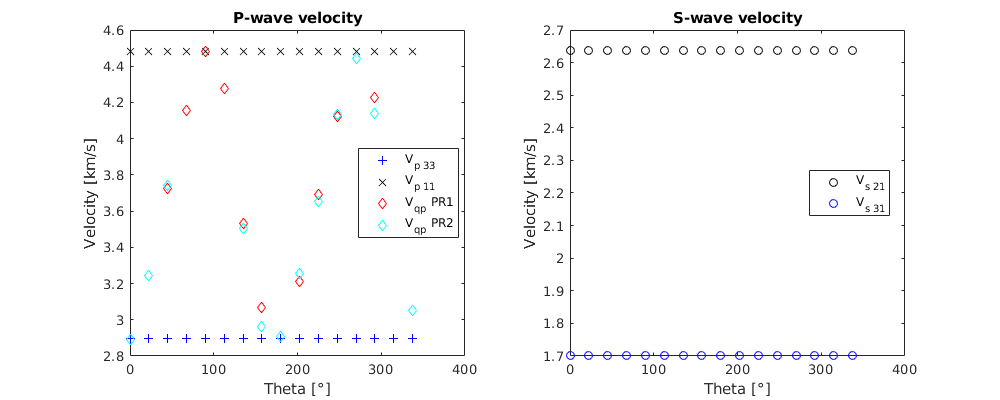

figure(122)
fig = figure('Position', [1 1 1000 400]);
subplot(1,2,1)
plot(Sample.Theta, Sample.Vp33, '+b');
hold on
plot(Sample.Theta, Sample.Vp11, 'xk');
plot(Sample.Theta(ind1), Sample.Vqp(ind1), 'dr');
plot(Sample.Theta(ind2), Sample.Vqp(ind2), 'dc');
xlabel('Theta [\circ]')
ylabel('Velocity [km/s]')
legend('V_{p 33}', 'V_{p 11}', 'V_{qp} PR1', 'V_{qp} PR2','Location','best')
title('P-wave velocity')

subplot(1,2,2)
plot(Sample.Theta, Sample.Vs21, 'ko');
hold on 
plot(Sample.Theta, Sample.Vs31, 'bo');
xlabel('Theta [\circ]')
ylabel('Velocity [km/s]')
legend('V_{s 21}','V_{s 31}','Location','best')
title('S-wave velocity')

### Assign C values

Sample.C11 = C11;
Sample.C33 = C33;
Sample.C44 = C44;
Sample.C66 = C66;
Sample.Vqp = Sample.Vqp;

### Find optimum delta

testdelta = -0.3:0.0001:0.5;
dtheta = -10:0.1:10;
nSample = Sample; 
JJ = zeros(length(dtheta),length(testdelta));
for i=1:length(dtheta)
    nSample.Theta = Sample.Theta + dtheta(i);
    J = costFunction_delta(nSample,testdelta);
    JJ(i,:) = J; 
end

[~, minind] = min(JJ(:));
[inda, indd] = ind2sub(size(JJ),minind);
 
thetapl = dtheta(inda);
delta = testdelta(indd);

### Plot final results 

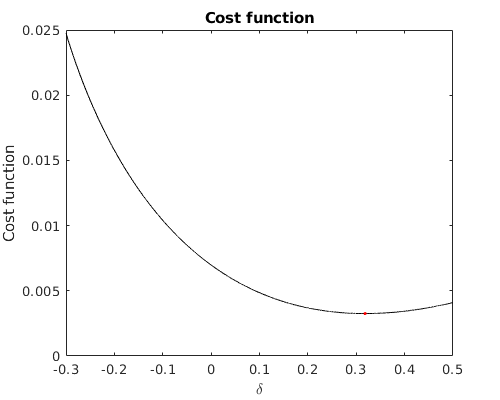

figure(343)
fig = figure('Position', [1 1 500 400]);
plot(testdelta, JJ(inda,:), 'k-');
hold on 
plot(testdelta(indd), JJ(inda,indd), 'r.','MarkerSize', 7);
xlabel('\delta')
ylabel('Cost function')
title('Cost function')

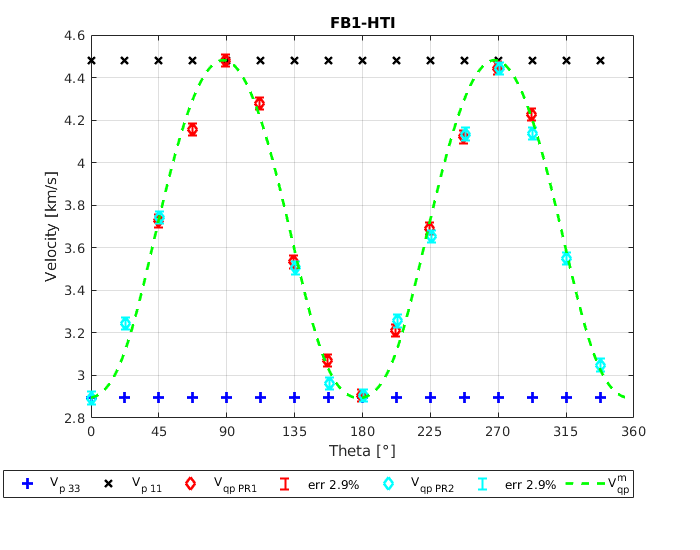


nSample.Theta = 0:1:360;
Vqp = get_Vqp_VTI(nSample,delta);
 
figure(1222)
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
plot(nSample.Theta-thetapl, Vqp, 'g--', 'LineWidth', 2)
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'V_{qp}^m', 'Location', 'southoutside', 'Orientation','horizontal')
title('FB1-HTI')
xticks(0:45:360)
xticklabels(0:45:360)
axis([0 360 2.8 4.6]);
grid on